### Regression Learner

V1模型用了全部的数据训练，无意义。

#### V2模型

*trainedModelGaussianProcessRegressionV2*这个模型，只用了前290条数据训练。取300之后的数据验证。

RMSE==51.656

红色线是预测的结果，蓝色线是实际结果。

trainDataV2=trainData(:,1:290);
gaussianPredictV2=...
    trainedModelGaussianProcessRegressionV2.predictFcn(inputFea(:,300:size(inputFea,2)));
rawPowrConsumV2=powerConsumTemp(:,300:end);
xAxis=linspace(1,size(rawPowrConsumV2,2),size(rawPowrConsumV2,2));
plot(xAxis,rawPowrConsumV2,'color','b');
hold on
plot(xAxis,gaussianPredictV2,'color','r')
hold off
legend('rawData','gaussianPredict','Location',"best");
xlim('auto')
ylim('auto')

#### Regression Learner 生成的训练函数

%% V2
% % function [trainedModel, validationRMSE] = trainRegressionModel(trainingData)
% % [trainedModel, validationRMSE] = trainRegressionModel(trainingData)
% % returns a trained regression model and its RMSE. This code recreates the
% % model trained in Regression Learner app. Use the generated code to
% % automate training the same model with new data, or to learn how to
% % programmatically train models.
% %
% %  Input:
% %      trainingData: a matrix with the same number of rows and data type as
% %       imported into the app.
% %
% %  Output:
% %      trainedModel: a struct containing the trained regression model. The
% %       struct contains various fields with information about the trained
% %       model.
% %
% %      trainedModel.predictFcn: a function to make predictions on new data.
% %
% %      validationRMSE: a double containing the RMSE. In the app, the
% %       History list displays the RMSE for each model.
% %
% % Use the code to train the model with new data. To retrain your model,
% % call the function from the command line with your original data or new
% % data as the input argument trainingData.
% %
% % For example, to retrain a regression model trained with the original data
% % set T, enter:
% %   [trainedModel, validationRMSE] = trainRegressionModel(T)
% %
% % To make predictions with the returned 'trainedModel' on new data T2, use
% %   yfit = trainedModel.predictFcn(T2)
% %
% % T2 must be a matrix containing only the predictor rows used for training.
% % For details, enter:
% %   trainedModel.HowToPredict
%
% % Auto-generated by MATLAB on 2021-10-05 12:08:31
%
%
% % Extract predictors and response
% % This code processes the data into the right shape for training the
% % model.
% % Convert input to table
% inputTable = array2table(trainingData', 'VariableNames', {'row_1', 'row_2', 'row_3', 'row_4', 'row_5', 'row_6', 'row_7', 'row_8'});
%
% predictorNames = {'row_1', 'row_2', 'row_3', 'row_4', 'row_5', 'row_6', 'row_7'};
% predictors = inputTable(:, predictorNames);
% response = inputTable.row_8;
% isCategoricalPredictor = [false, false, false, false, false, false, false];
%
% % Train a regression model
% % This code specifies all the model options and trains the model.
% regressionGP = fitrgp(...
%     predictors, ...
%     response, ...
%     'BasisFunction', 'constant', ...
%     'KernelFunction', 'exponential', ...
%     'Standardize', true);
%
% % Create the result struct with predict function
% predictorExtractionFcn = @(x) array2table(x', 'VariableNames', predictorNames);
% gpPredictFcn = @(x) predict(regressionGP, x);
% trainedModel.predictFcn = @(x) gpPredictFcn(predictorExtractionFcn(x));
%
% % Add additional fields to the result struct
% trainedModel.RegressionGP = regressionGP;
% trainedModel.About = 'This struct is a trained model exported from Regression Learner R2019a.';
% trainedModel.HowToPredict = sprintf('To make predictions on a new predictor row matrix, X, use: \n  yfit = c.predictFcn(X) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nX must contain exactly 7 rows because this model was trained using 7 predictors. \nX must contain only predictor rows in exactly the same order and format as your training \ndata. Do not include the response row or any rows you did not import into the app. \n \nFor more information, see How to predict using an exported model.');
%
% % Extract predictors and response
% % This code processes the data into the right shape for training the
% % model.
% % Convert input to table
% inputTable = array2table(trainingData', 'VariableNames', {'row_1', 'row_2', 'row_3', 'row_4', 'row_5', 'row_6', 'row_7', 'row_8'});
%
% predictorNames = {'row_1', 'row_2', 'row_3', 'row_4', 'row_5', 'row_6', 'row_7'};
% predictors = inputTable(:, predictorNames);
% response = inputTable.row_8;
% isCategoricalPredictor = [false, false, false, false, false, false, false];
%
% % Perform cross-validation
% partitionedModel = crossval(trainedModel.RegressionGP, 'KFold', 5);
%
% % Compute validation predictions
% validationPredictions = kfoldPredict(partitionedModel);
%
% % Compute validation RMSE
% validationRMSE = sqrt(kfoldLoss(partitionedModel, 'LossFun', 'mse'));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % V4
% % function [trainedModel, validationRMSE] = trainRegressionModel(trainingData)
% % [trainedModel, validationRMSE] = trainRegressionModel(trainingData)
% % returns a trained regression model and its RMSE. This code recreates the
% % model trained in Regression Learner app. Use the generated code to
% % automate training the same model with new data, or to learn how to
% % programmatically train models.
% %
% %  Input:
% %      trainingData: a matrix with the same number of rows and data type as
% %       imported into the app.
% %
% %  Output:
% %      trainedModel: a struct containing the trained regression model. The
% %       struct contains various fields with information about the trained
% %       model.
% %
% %      trainedModel.predictFcn: a function to make predictions on new data.
% %
% %      validationRMSE: a double containing the RMSE. In the app, the
% %       History list displays the RMSE for each model.
% %
% % Use the code to train the model with new data. To retrain your model,
% % call the function from the command line with your original data or new
% % data as the input argument trainingData.
% %
% % For example, to retrain a regression model trained with the original data
% % set T, enter:
% %   [trainedModel, validationRMSE] = trainRegressionModel(T)
% %
% % To make predictions with the returned 'trainedModel' on new data T2, use
% %   yfit = trainedModel.predictFcn(T2)
% %
% % T2 must be a matrix containing only the predictor rows used for training.
% % For details, enter:
% %   trainedModel.HowToPredict
%
% % Auto-generated by MATLAB on 2021-10-07 17:11:54
%
%
% % Extract predictors and response
% % This code processes the data into the right shape for training the
% % model.
% % Convert input to table
% inputTable = array2table(trainingData', 'VariableNames', {'row_1', 'row_2', 'row_3', 'row_4', 'row_5', 'row_6', 'row_7', 'row_8', 'row_9', 'row_10', 'row_11', 'row_12', 'row_13', 'row_14', 'row_15'});
%
% predictorNames = {'row_1', 'row_2', 'row_3', 'row_4', 'row_5', 'row_6', 'row_7', 'row_8', 'row_9', 'row_10', 'row_11', 'row_12', 'row_13', 'row_14'};
% predictors = inputTable(:, predictorNames);
% response = inputTable.row_15;
% isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false];
%
% % Train a regression model
% % This code specifies all the model options and trains the model.
% regressionGP = fitrgp(...
%     predictors, ...
%     response, ...
%     'BasisFunction', 'constant', ...
%     'KernelFunction', 'matern52', ...
%     'Standardize', true);
%
% % Create the result struct with predict function
% predictorExtractionFcn = @(x) array2table(x', 'VariableNames', predictorNames);
% gpPredictFcn = @(x) predict(regressionGP, x);
% trainedModel.predictFcn = @(x) gpPredictFcn(predictorExtractionFcn(x));
%
% % Add additional fields to the result struct
% trainedModel.RegressionGP = regressionGP;
% trainedModel.About = 'This struct is a trained model exported from Regression Learner R2019a.';
% trainedModel.HowToPredict = sprintf('To make predictions on a new predictor row matrix, X, use: \n  yfit = c.predictFcn(X) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nX must contain exactly 14 rows because this model was trained using 14 predictors. \nX must contain only predictor rows in exactly the same order and format as your training \ndata. Do not include the response row or any rows you did not import into the app. \n \nFor more information, see How to predict using an exported model.');
%
% % Extract predictors and response
% % This code processes the data into the right shape for training the
% % model.
% % Convert input to table
% inputTable = array2table(trainingData', 'VariableNames', {'row_1', 'row_2', 'row_3', 'row_4', 'row_5', 'row_6', 'row_7', 'row_8', 'row_9', 'row_10', 'row_11', 'row_12', 'row_13', 'row_14', 'row_15'});
%
% predictorNames = {'row_1', 'row_2', 'row_3', 'row_4', 'row_5', 'row_6', 'row_7', 'row_8', 'row_9', 'row_10', 'row_11', 'row_12', 'row_13', 'row_14'};
% predictors = inputTable(:, predictorNames);
% response = inputTable.row_15;
% isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false];
%
% % Perform cross-validation
% partitionedModel = crossval(trainedModel.RegressionGP, 'KFold', 5);
%
% % Compute validation predictions
% validationPredictions = kfoldPredict(partitionedModel);
%
% % Compute validation RMSE
% validationRMSE = sqrt(kfoldLoss(partitionedModel, 'LossFun', 'mse'));


#### V3模型，减少输入变量

模型V3选择了1,2,4,7行作为输入变量，**没有启用PCA！！！！！V3的命名是错的！！PCA is off!!**

feaInd=[1,2,4,7];
trainDataV3=trainData(feaInd,1:290);
gaussianPredictV3=trainedModelGaussianProcessRegressionV3PCAOn.predictFcn(inputFea(:,300:size(inputFea,2)));
% 这里输入还是要全部输入，不能只输入feaInd
rawPowrConsumV3=powerConsumTemp(:,300:end);
xAxis=linspace(1,size(rawPowrConsumV3,2),size(rawPowrConsumV3,2));
plot(xAxis,rawPowrConsumV3,'color','b');
hold on;
plot(xAxis,gaussianPredictV3,'color','r',"LineStyle",":","LineWidth",2);
hold off
legend('rawData','gaussianPredict','Location',"best");
xlim('auto')
ylim('auto')

#### V4模型，使用V3数据集，增加特征数

数据V3中增加特征数，但是少了5月20日的数据

数据号是V3，但对应输入网络的特征号是V4。此后都用V3数据集训练。

训练集上 RMSE=48.296

inputFeaV4=v3(1:14,2:end);
powerConsumV4=v3(16,2:end)*1000;
trainDataV4=[inputFeaV4;powerConsumV4];
trainDataV4=trainDataV4(:,1:290);

预测

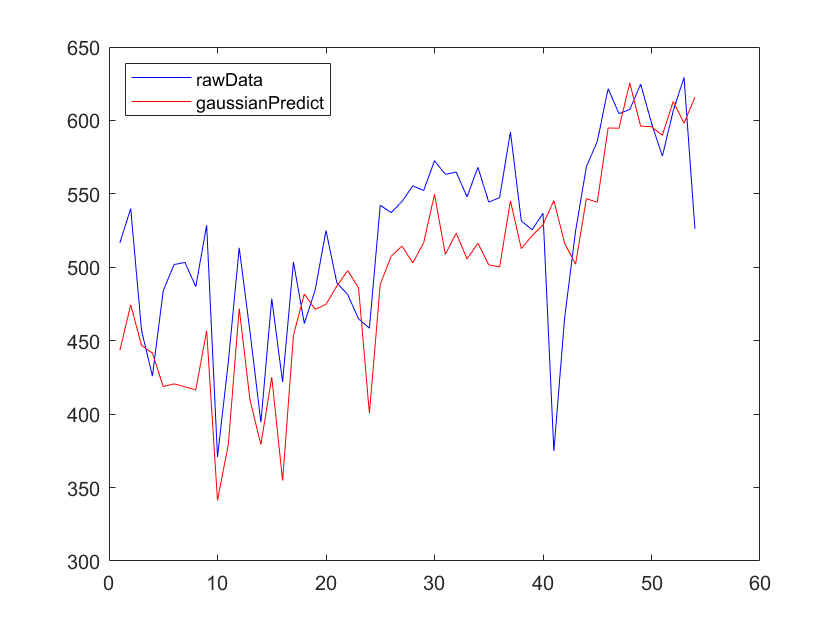

gaussianPredictV4=...
    trainedModeltrainedModelGaussianProcessRegressionV4.predictFcn(inputFeaV4(:,300:end));
rawPowrConsumV4=powerConsumV4(:,300:end);
xAxis=linspace(1,size(rawPowrConsumV4,2),size(rawPowrConsumV4,2));
plot(xAxis,rawPowrConsumV4,'color','b');
hold on
plot(xAxis,gaussianPredictV4,'color','r')
hold off
legend('rawData','gaussianPredict','Location',"northwest");
xlim('auto')
ylim('auto')

gaussianPredictV4RSquare=1-sum((rawPowrConsumV4-gaussianPredictV4').^2)/sum((rawPowrConsumV4-mean(rawPowrConsumV4')).^2)

gaussianPredictV4RSquare = 0.3529

### Neural Network Fitting——Nftool

#### APP生成的代码

% % Solve an Input-Output Fitting problem with a Neural Network
% % Script generated by Neural Fitting app
% % Created 07-Oct-2021 20:33:38
% %
% % This script assumes these variables are defined:
% %
% %   inputFeaNftool - input data.
% %   powerConsumNftool - target data.
% 
% x = inputFeaNftool;
% t = powerConsumNftool;
% 
% % Choose a Training Function
% % For a list of all training functions type: help nntrain
% % 'trainlm' is usually fastest.
% % 'trainbr' takes longer but may be better for challenging problems.
% % 'trainscg' uses less memory. Suitable in low memory situations.
% trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
% 
% % Create a Fitting Network
% hiddenLayerSize = 30;
% net = fitnet(hiddenLayerSize,trainFcn);
% 
% % Choose Input and Output Pre/Post-Processing Functions
% % For a list of all processing functions type: help nnprocess
% net.input.processFcns = {'removeconstantrows','mapminmax'};
% net.output.processFcns = {'removeconstantrows','mapminmax'};
% 
% % Setup Division of Data for Training, Validation, Testing
% % For a list of all data division functions type: help nndivision
% net.divideFcn = 'dividerand';  % Divide data randomly
% net.divideMode = 'sample';  % Divide up every sample
% net.divideParam.trainRatio = 80/100;
% net.divideParam.valRatio = 10/100;
% net.divideParam.testRatio = 10/100;
% 
% % Choose a Performance Function
% % For a list of all performance functions type: help nnperformance
% net.performFcn = 'mse';  % Mean Squared Error
% 
% % Choose Plot Functions
% % For a list of all plot functions type: help nnplot
% net.plotFcns = {'plotperform','plottrainstate','ploterrhist', ...
%     'plotregression', 'plotfit'};
% 
% % Train the Network
% [net,tr] = train(net,x,t);
% 
% % Test the Network
% y = net(x);
% e = gsubtract(t,y);
% performance = perform(net,t,y)
% 
% % Recalculate Training, Validation and Test Performance
% trainTargets = t .* tr.trainMask{1};
% valTargets = t .* tr.valMask{1};
% testTargets = t .* tr.testMask{1};
% trainPerformance = perform(net,trainTargets,y)
% valPerformance = perform(net,valTargets,y)
% testPerformance = perform(net,testTargets,y)
% 
% % View the Network
% view(net)
% 
% % Plots
% % Uncomment these lines to enable various plots.
% %figure, plotperform(tr)
% %figure, plottrainstate(tr)
% %figure, ploterrhist(e)
% %figure, plotregression(t,y)
% %figure, plotfit(net,x,t)
% 
% % Deployment
% % Change the (false) values to (true) to enable the following code blocks.
% % See the help for each generation function for more information.
% if (false)
%     % Generate MATLAB function for neural network for application
%     % deployment in MATLAB scripts or with MATLAB Compiler and Builder
%     % tools, or simply to examine the calculations your trained neural
%     % network performs.
%     genFunction(net,'myNeuralNetworkFunction');
%     y = myNeuralNetworkFunction(x);
% end
% if (false)
%     % Generate a matrix-only MATLAB function for neural network code
%     % generation with MATLAB Coder tools.
%     genFunction(net,'myNeuralNetworkFunction','MatrixOnly','yes');
%     y = myNeuralNetworkFunction(x);
% end
% if (false)
%     % Generate a Simulink diagram for simulation or deployment with.
%     % Simulink Coder tools.
%     gensim(net);
% end


#### nntool中利用NftoolNetV1进行预测

plot(xAxis,NftoolNetV1_TestOutputs,'color','b');
hold on
plot(xAxis,powerConsumNftoolTest,'color','r')
hold off
legend('NftoolNetV1','rawData','Location',"best");
xlim('auto')
ylim('auto')

计算RMSE


$$$$RMSE=\sqrt{\frac{1}{m}\sum\limits_{i=1}^{m}(y_i-\hat{y})^2}$$$$


NftoolNetV1RMSE=sqrt(sum((NftoolNetV1_TestOutputs-powerConsumNftoolTest).^2)/size(powerConsumNftoolTest,2))

计算RSquare


$$$$R^2=1-\frac{\sum\limits_{i=1}^{m}(y_i-\hat{y})^2_i}{\sum\limits_{i=1}^m(y_i-\bar{y})^2}$$$$


NftoolNetV1RSquare=1-sum((NftoolNetV1_TestOutputs-powerConsumNftoolTest).^2)/sum((mean(powerConsumNftoolTest)-powerConsumNftoolTest).^2)

### Time Series——Ntstool

#### APP 生成的代码

% % Solve an Autoregression Problem with External Input with a NARX Neural Network
% % Script generated by Neural Time Series app
% % Created 07-Oct-2021 21:18:20
% %
% % This script assumes these variables are defined:
% %
% %   inputFeaNftool - input time series.
% %   powerConsumNftool - feedback time series.
% 
% X = tonndata(inputFeaNftool,true,false);
% T = tonndata(powerConsumNftool,true,false);
% 
% % Choose a Training Function
% % For a list of all training functions type: help nntrain
% % 'trainlm' is usually fastest.
% % 'trainbr' takes longer but may be better for challenging problems.
% % 'trainscg' uses less memory. Suitable in low memory situations.
% trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
% 
% % Create a Nonlinear Autoregressive Network with External Input
% inputDelays = 1:3;
% feedbackDelays = 1:3;
% hiddenLayerSize = 40;
% net = narxnet(inputDelays,feedbackDelays,hiddenLayerSize,'open',trainFcn);
% 
% % Choose Input and Feedback Pre/Post-Processing Functions
% % Settings for feedback input are automatically applied to feedback output
% % For a list of all processing functions type: help nnprocess
% % Customize input parameters at: net.inputs{i}.processParam
% % Customize output parameters at: net.outputs{i}.processParam
% net.inputs{1}.processFcns = {'removeconstantrows','mapminmax'};
% net.inputs{2}.processFcns = {'removeconstantrows','mapminmax'};
% 
% % Prepare the Data for Training and Simulation
% % The function PREPARETS prepares timeseries data for a particular network,
% % shifting time by the minimum amount to fill input states and layer
% % states. Using PREPARETS allows you to keep your original time series data
% % unchanged, while easily customizing it for networks with differing
% % numbers of delays, with open loop or closed loop feedback modes.
% [x,xi,ai,t] = preparets(net,X,{},T);
% 
% % Setup Division of Data for Training, Validation, Testing
% % For a list of all data division functions type: help nndivision
% net.divideFcn = 'dividerand';  % Divide data randomly
% net.divideMode = 'time';  % Divide up every sample
% net.divideParam.trainRatio = 80/100;
% net.divideParam.valRatio = 10/100;
% net.divideParam.testRatio = 10/100;
% 
% % Choose a Performance Function
% % For a list of all performance functions type: help nnperformance
% net.performFcn = 'mse';  % Mean Squared Error
% 
% % Choose Plot Functions
% % For a list of all plot functions type: help nnplot
% net.plotFcns = {'plotperform','plottrainstate', 'ploterrhist', ...
%     'plotregression', 'plotresponse', 'ploterrcorr', 'plotinerrcorr'};
% 
% % Train the Network
% [net,tr] = train(net,x,t,xi,ai);
% 
% % Test the Network
% y = net(x,xi,ai);
% e = gsubtract(t,y);
% performance = perform(net,t,y)
% 
% % Recalculate Training, Validation and Test Performance
% trainTargets = gmultiply(t,tr.trainMask);
% valTargets = gmultiply(t,tr.valMask);
% testTargets = gmultiply(t,tr.testMask);
% trainPerformance = perform(net,trainTargets,y)
% valPerformance = perform(net,valTargets,y)
% testPerformance = perform(net,testTargets,y)
% 
% % View the Network
% view(net)
% 
% % Plots
% % Uncomment these lines to enable various plots.
% %figure, plotperform(tr)
% %figure, plottrainstate(tr)
% %figure, ploterrhist(e)
% %figure, plotregression(t,y)
% %figure, plotresponse(t,y)
% %figure, ploterrcorr(e)
% %figure, plotinerrcorr(x,e)
% 
% % Closed Loop Network
% % Use this network to do multi-step prediction.
% % The function CLOSELOOP replaces the feedback input with a direct
% % connection from the outout layer.
% netc = closeloop(net);
% netc.name = [net.name ' - Closed Loop'];
% view(netc)
% [xc,xic,aic,tc] = preparets(netc,X,{},T);
% yc = netc(xc,xic,aic);
% closedLoopPerformance = perform(net,tc,yc)
% 
% % Multi-step Prediction
% % Sometimes it is useful to simulate a network in open-loop form for as
% % long as there is known output data, and then switch to closed-loop form
% % to perform multistep prediction while providing only the external input.
% % Here all but 5 timesteps of the input series and target series are used
% % to simulate the network in open-loop form, taking advantage of the higher
% % accuracy that providing the target series produces:
% numTimesteps = size(x,2);
% knownOutputTimesteps = 1:(numTimesteps-5);
% predictOutputTimesteps = (numTimesteps-4):numTimesteps;
% X1 = X(:,knownOutputTimesteps);
% T1 = T(:,knownOutputTimesteps);
% [x1,xio,aio] = preparets(net,X1,{},T1);
% [y1,xfo,afo] = net(x1,xio,aio);
% % Next the the network and its final states will be converted to
% % closed-loop form to make five predictions with only the five inputs
% % provided.
% x2 = X(1,predictOutputTimesteps);
% [netc,xic,aic] = closeloop(net,xfo,afo);
% [y2,xfc,afc] = netc(x2,xic,aic);
% multiStepPerformance = perform(net,T(1,predictOutputTimesteps),y2)
% % Alternate predictions can be made for different values of x2, or further
% % predictions can be made by continuing simulation with additional external
% % inputs and the last closed-loop states xfc and afc.
% 
% % Step-Ahead Prediction Network
% % For some applications it helps to get the prediction a timestep early.
% % The original network returns predicted y(t+1) at the same time it is
% % given y(t+1). For some applications such as decision making, it would
% % help to have predicted y(t+1) once y(t) is available, but before the
% % actual y(t+1) occurs. The network can be made to return its output a
% % timestep early by removing one delay so that its minimal tap delay is now
% % 0 instead of 1. The new network returns the same outputs as the original
% % network, but outputs are shifted left one timestep.
% nets = removedelay(net);
% nets.name = [net.name ' - Predict One Step Ahead'];
% view(nets)
% [xs,xis,ais,ts] = preparets(nets,X,{},T);
% ys = nets(xs,xis,ais);
% stepAheadPerformance = perform(nets,ts,ys)
% 
% % Deployment
% % Change the (false) values to (true) to enable the following code blocks.
% % See the help for each generation function for more information.
% if (false)
%     % Generate MATLAB function for neural network for application
%     % deployment in MATLAB scripts or with MATLAB Compiler and Builder
%     % tools, or simply to examine the calculations your trained neural
%     % network performs.
%     genFunction(net,'myNeuralNetworkFunction');
%     y = myNeuralNetworkFunction(x,xi,ai);
% end
% if (false)
%     % Generate a matrix-only MATLAB function for neural network code
%     % generation with MATLAB Coder tools.
%     genFunction(net,'myNeuralNetworkFunction','MatrixOnly','yes');
%     x1 = cell2mat(x(1,:));
%     x2 = cell2mat(x(2,:));
%     xi1 = cell2mat(xi(1,:));
%     xi2 = cell2mat(xi(2,:));
%     y = myNeuralNetworkFunction(x1,x2,xi1,xi2);
% end
% if (false)
%     % Generate a Simulink diagram for simulation or deployment with.
%     % Simulink Coder tools.
%     gensim(net);
% end

#### 预测

MSE=6008

没有timedelay，无法进行测试

### Nntool

#### NntoolNetV1测试结果

plot(xAxis,NntoolNetV1_TestOutputs,'color','b');
hold on
plot(xAxis,powerConsumNftoolTest,'color','r')
hold off
legend('NntoolNetV1','rawData','Location',"best");
xlim('auto')
ylim('auto')

计算RMSE

NntoolNetV1RMSE=sqrt(sum((NntoolNetV1_TestOutputs-powerConsumNftoolTest).^2)/size(powerConsumNftoolTest,2))

太大了！！

#### 径向基函数（司守奎428页代码）

NEWRB, neurons = 0, MSE = 0.181135
NEWRB, neurons = 50, MSE = 0.016836


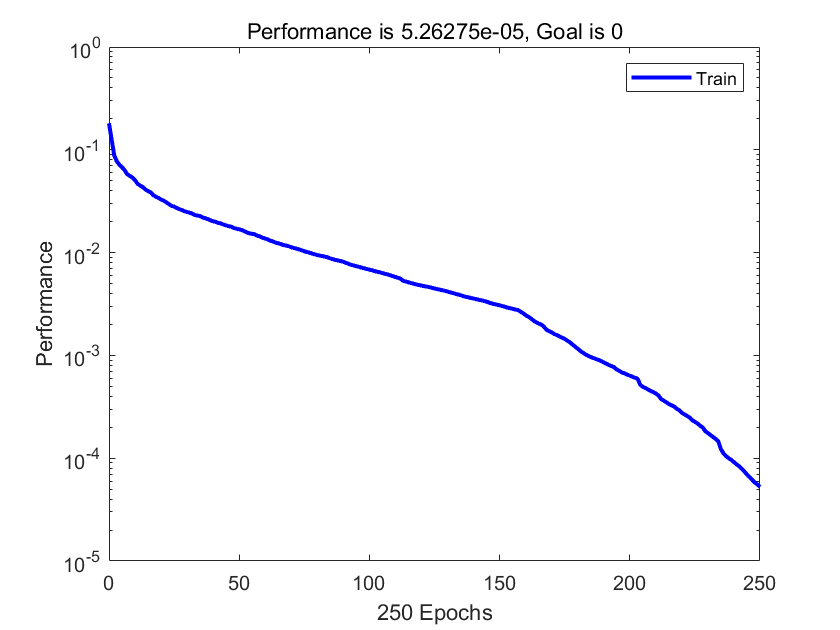

NEWRB, neurons = 100, MSE = 0.00682634
NEWRB, neurons = 150, MSE = 0.00307328
NEWRB, neurons = 200, MSE = 0.000634943
NEWRB, neurons = 250, MSE = 5.26275e-05


% 训练集自变量因变量规格化到-1,1
inputFeaV5=inputFeaV4(:,1:290);
[inputFeaV5Norm,inputFeaV5Setting]=mapminmax(inputFeaV5);
rawPowrConsumV5Train=trainDataV4(15,:);% 训练时用的耗电量
[rawPowrConsumV5TrainNorm,rawPowrConsumV5TrainSetting]=mapminmax(rawPowrConsumV5Train);
% 训练RBF网络
MN=500;spread=0.72;
RBFNetV1=newrb(inputFeaV5Norm,rawPowrConsumV5TrainNorm,0,spread,MN);

% 开始预测
inputFeaV5Test=inputFeaV4(:,300:end);
inputFeaV5TestNorm=mapminmax('apply',inputFeaV5Test,inputFeaV5Setting);
RBFNetV1Predict=sim(RBFNetV1,inputFeaV5TestNorm);% start predicting
RBFNetV1PredictUnNorm=mapminmax('reverse',RBFNetV1Predict,rawPowrConsumV5TrainSetting);
%%
rawPowrConsumV4=powerConsumV4(:,300:end);% 测试时，用300列之后的实际耗电量
xAxis=linspace(1,size(rawPowrConsumV4,2),size(rawPowrConsumV4,2));
%% 计算RSquare
RBFNetV1PredictUnNormRSquare=...
    1-sum((RBFNetV1PredictUnNorm-rawPowrConsumV4).^2)/sum((mean(rawPowrConsumV4)-rawPowrConsumV4).^2)

RBFNetV1PredictUnNormRSquare = -0.4266

RSquare为负数，还不如瞎猜。

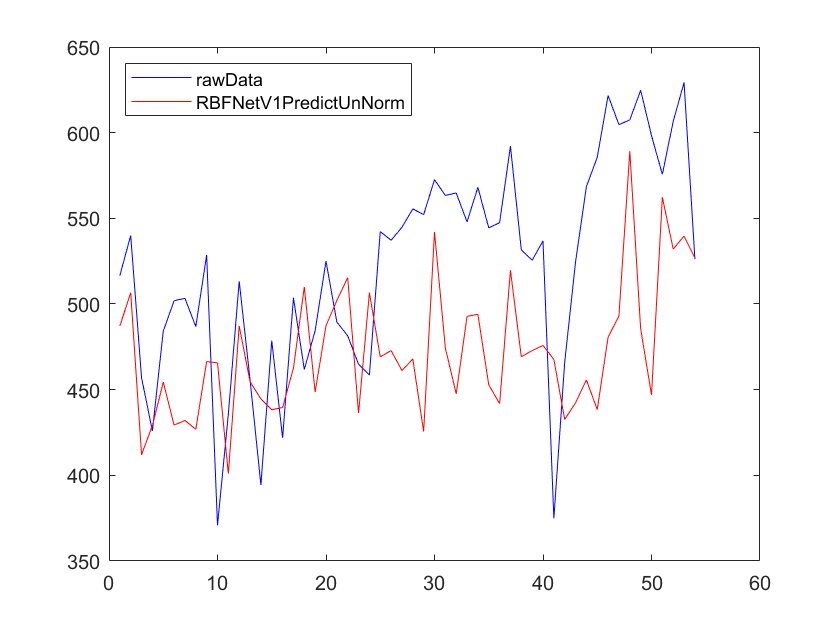

%%
plot(xAxis,rawPowrConsumV4,'color','b');
hold on
plot(xAxis,RBFNetV1PredictUnNorm,'color','r')
hold off
legend('rawData','RBFNetV1PredictUnNorm','Location',"northwest");
xlim('auto')
ylim('auto')